An overview of the segmentation pre-processing that should provide intuition on how to optimize images for the graph cut step. This covers the first few steps in `simpleSegmentation.m`  

For a more detailed explanation, see:

Chiu et al (2010) Automatic segmentation of seven retinal layers in SDOCT images congruent with expert manual segmentation. *Optics Express, *18(18), 19413-19428

% Make sure OCT tools is on your path
addpath(genpath('C:\Users\sarap\Dropbox\Sara and Jay Shared\oct choroid\OCT-tools'));
% Set imDir to the location where the edited OCT images are saved.
imDir = '';

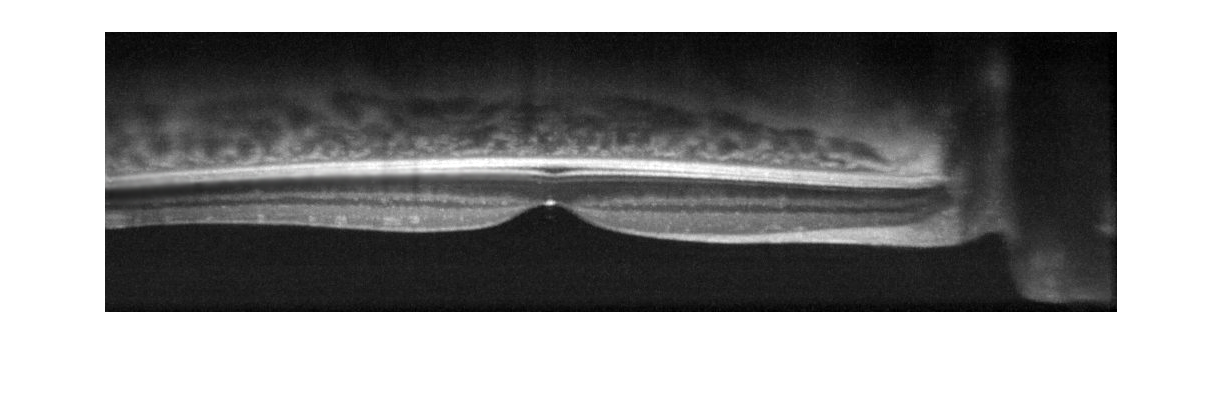

% Import an OCT image
im = imread([imDir, '2.png']);
imshow(im);

% The OCT image dimensions
% The units are # pixels, # pixels, RGB. 
size(im)

ans =          280        1012           3


% The R, G and B channels are unnecessary, so simplify:
im = rgb2gray(im);
size(im)

ans =          280        1012


% The class is also uint8, change this to double (normal numbers)
im = im2double(im);

% At this point, it's helpful to save a copy of the original image before
% applying any major edits to 'im'.
originalImage = im;

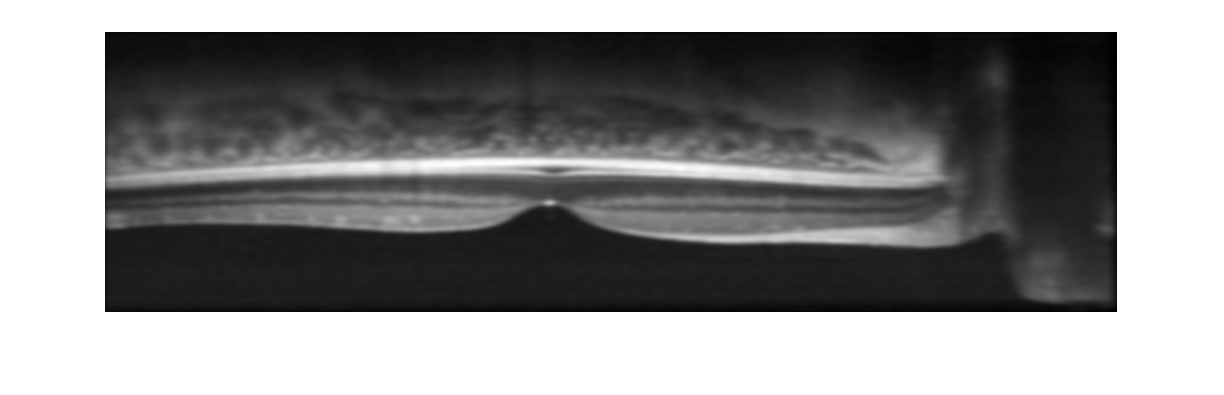

% Blur the image. This is ususally the first step
im = imfilter(im, fspecial('gaussian', [5 20], 3));
imshow(im)

% Some algorithms shrink the image too. I haven't, but this might be
% good to experiment with. That would go here with something like:
% im = imresize(im, 0.5);

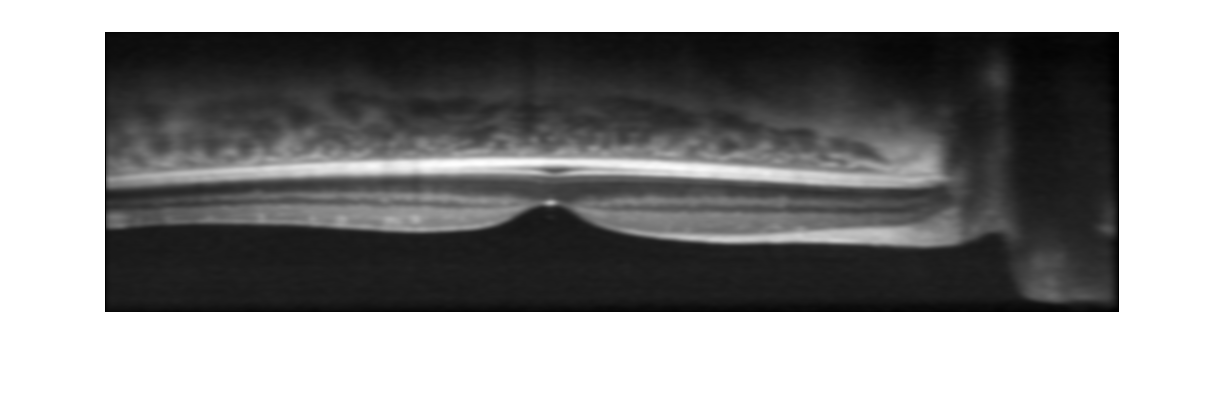

% Pad the image
% The segmentation code uses Dijkstra's algorithm to find the lowest
% weighted path across an image. Essentially this is the horizontal line
% with the lowest total weight. Each pixel of an image is assigned a weight
% based on the pixel's intensity (0 = black, 1 = white, 0.5 = gray, etc).
% More on this at the end.

% To ensure the algorithm actually makes it across the image, we add black
% (aka 0, the lowest weight) edges to the image.
im = padarray(im, [0, 1], 0, 'both');
imshow(im)

% You should be able to see the 2nd number (# of x pixels) has increased
imSize = size(im)

imSize =          280        1014


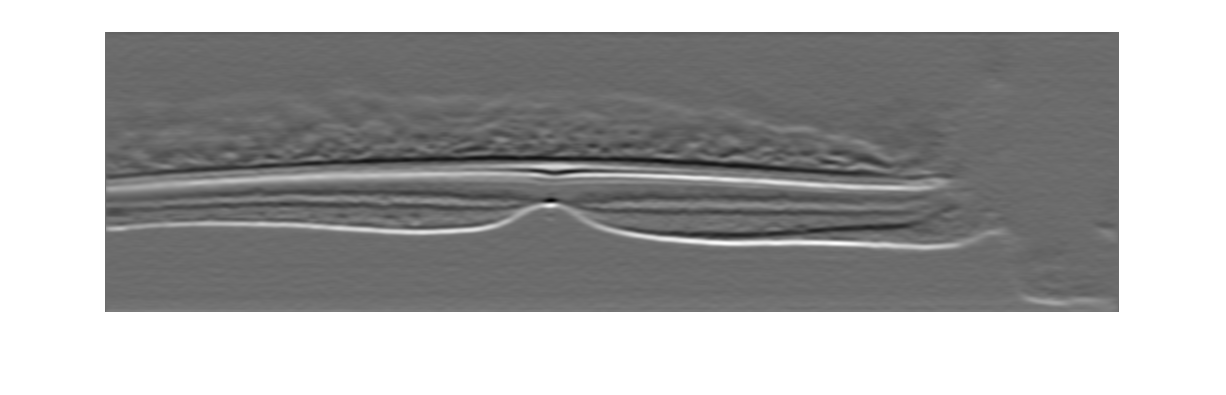

% Now take the vertical gradient (dF/dy)
imGrad = zeros(imSize);
% Computed by row, but I think there's a gradient2 function that would be
% better to use here. To do...
for i = 1:imSize(2)
    imGrad(:, i) = -1*gradient(im(:, i), 2);
end
imGrad = (imGrad-min(imGrad(:)))/(max(imGrad(:))-min(imGrad(:)));
imshow(imGrad)

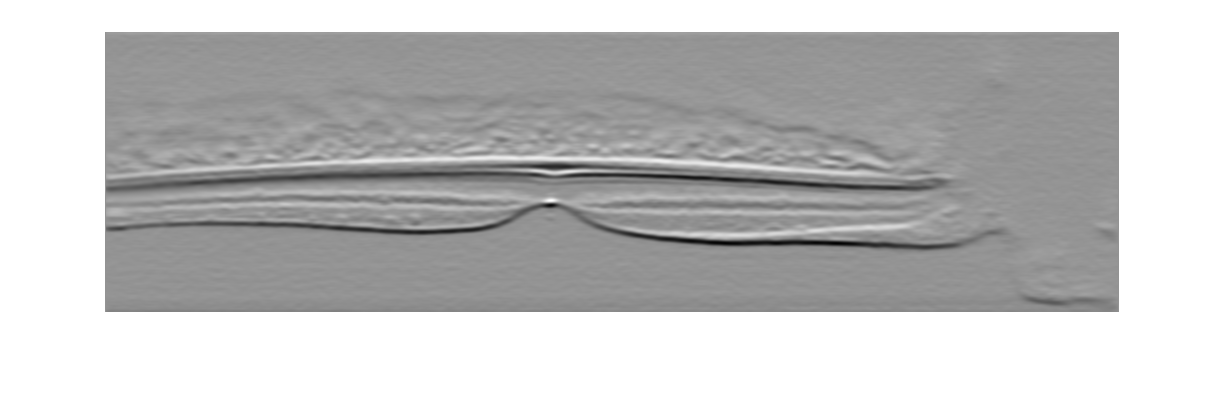

% Here's the inverse vertical gradient
imGradInv = -1*imGrad + 1;
imshow(imGradInv)

% A nice example of how Dijkstra's algorithm works is shown in Figure 4 of
% the Chiu et al (2010) article referenced above. Long story short, the
% algorithm tries to draw a horizontal line across the image hitting the
% darkest pixels. You can see the two boundaries we like to segment in the
% two images above - the algorithm is performed on these images, not the
% original. 
% You can hopefully also see why we crop the OCT images before this step,
% particularly on the right. There's no dark line for the algorithm to
% follow. Similarly, a well-rotated image (boundaries are as flat as
% possible) will be easier for the algorithm to trace.